# Estimate Bit Error Rate for 16-QAM OFDM in AWGN and LTI channel

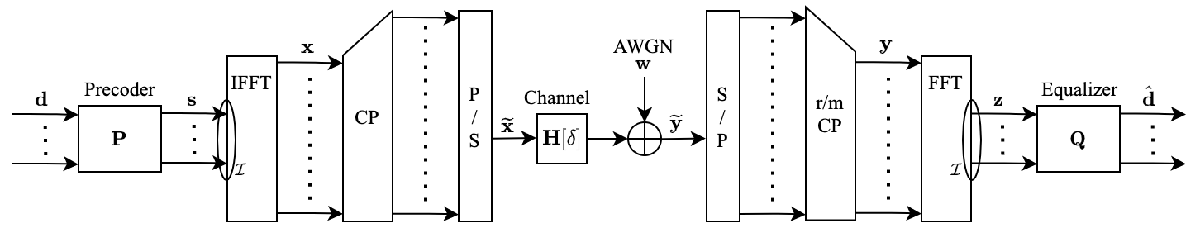

CLEAN_RUN = true;

if CLEAN_RUN
    clear; clc; clf; %#ok<UNRCH>
end

DEBUG = false;

Simulation parameters.

M = 16;                 % 16-QAM
k = log2(M);            % Bits per symbol

fft_size = 128;         % FFT size
cp_length = 9;          % Cyclic prefix length

mod_symbol_size = 128;   % Modulation symbol size
used_subcarrier_idx = (1:128);

N_block = 1e3;          % Number of blocks(OFDM symbols)
N_trial = 1e3;          % Number of Monte Carlo trials

EbNo = (0:5:30);            % Eb/No(dB)
SNR = EbNo + 10*log10(k);   % Convert Eb/No to SNR(dB)

Block functions.

% Precoder
P = eye(mod_symbol_size);

% Add CP
% Same as
% cp = ifft_data(end-cp_length+1: end);
% cp_data = [cp; ifft_data];
CP_matrix = [zeros(cp_length, fft_size-cp_length) eye(cp_length); eye(fft_size)];

% Remove CP
% Same as
% rx_rm_cp = rx_parallel(cp_length+1: end);
rm_CP_matrix = [zeros(fft_size, cp_length) eye(fft_size)];

% Pad unused subcarier
pad_unused_sub_matrix = [zeros( used_subcarrier_idx(1)-1, mod_symbol_size ); eye(mod_symbol_size); zeros( fft_size-used_subcarrier_idx(end), mod_symbol_size )];

% Remove unused subcarier
rm_unused_sub_matrix = transpose(pad_unused_sub_matrix);

Channel.

% Power delay profile
c_dB = [0 -Inf -Inf -3 -Inf -Inf -Inf -Inf -Inf -5];

% Channel impulse response
c = db2mag(c_dB)';

% Channel frequency response
C_k = fft(c, fft_size); % no normalization

% Circulant matrix
C_circ = circulant_matrix(c, fft_size+cp_length);  % C_circ == T

% conv(x,c) == C_low*x
C_low = convmtx(c, fft_size);
% L = remove_spread(C_low*x);
L = [eye(fft_size) zeros(fft_size, cp_length)] * C_low;

if DEBUG
    figure   %#ok<UNRCH>
    stem(c)
    set(gca, 'yscale', 'log');
end

Equalizers.

% Zero-forcing
Q_ZF_all_sub = diag(1./C_k);
Q_ZF = Q_ZF_all_sub(used_subcarrier_idx, used_subcarrier_idx);

Monte Carlo simulation.

% BER estimation
ber_est = zeros(size(EbNo));

tic

for n = 1:length(EbNo)
    % Reset the error bit counter
    numErrs = 0;
    
    % MMSE equalizer
    % MMSE_snr = k * db2mag(SNR(n));
    MMSE_snr = inf;
    Q_MMSE = L* inv(L*L' + (1/MMSE_snr)*eye(fft_size));
    
    for trial_idx = 1:N_trial
        % ---------- Tx ----------
        % Generate binary data and convert it to decimal symbols
        bin_data = randi([0, 1], k, mod_symbol_size * N_block)';
        dec_data = bi2de(bin_data, 'left-msb');
        
        % QAM mapping and normalize the symbol energy
        mod_symbol_data_stream = qammod(dec_data, M, 'UnitAveragePower', true);
        mod_symbol_data_block = reshape(mod_symbol_data_stream, mod_symbol_size, N_block);
        
        % Debug. Plot constellation:
        if DEBUG && (n == 1) && (trial_idx == 1) && (block_idx == 1)
            scatterplot(mod_symbol_data_stream), grid;
            title('Constellation');
        end
        
        % Precoder
        precode_data = P * mod_symbol_data_block;
        
        % Pad unused subcarriers
        pad_data = pad_unused_sub_matrix * precode_data;
        
        % IFFT
        % sqrt(fft_size) for normalizing the power of transmit symbol to 1
        ifft_data = (sqrt(fft_size)) * ifft(pad_data);
        
        % Cyclic prefix
        cp_data = CP_matrix * ifft_data;
        
        % Parallel to serial
        txSig = reshape(cp_data, 1, []);
        
        % ------- Channel --------
        channel_out = conv(txSig, c);
        
        % Remove the part of the signal that was spread by the channel
        channel_out_rm_spread = channel_out(1: end-length(c)+1);
        
        % AWGN noise
        rxSig = awgn(channel_out_rm_spread, SNR(n));
        
        %% Same as rxSig = awgn(channel_out_rm_spread, SNR(n))
        % noise = 1/sqrt(2)*(randn(1,length(txSig)) + 1i*randn(1,length(txSig))); % white guassian noise, 0dB variance
        % rxSig = txSig + 10^(-snr/20)*noise; % additive white gaussian noise
        
        % ---------- Rx ----------
        %Serial to parallel
        rx_parallel = reshape(channel_out_rm_spread, fft_size+cp_length, N_block);
        
        % Remove cyclic prefix
        rx_rm_cp = rm_CP_matrix * rx_parallel;
        
        % FFT
        % 1/sqrt(fft_size) for normalizing the power of transmit symbol to 1
        rx_fft = (1/sqrt(fft_size)) * fft(rx_rm_cp);
        
        % Remove unused subcarriers
        rx_used_subcarrier = rm_unused_sub_matrix * rx_fft;
        
        % Equalizer
        eq_out = Q_MMSE * rx_used_subcarrier;
        
        % QAM demodulate
        rx_dec_data = qamdemod(eq_out, M, 'UnitAveragePower', true);
        rx_bin_data = de2bi(rx_dec_data, k, 'left-msb');
        
        % Calculate the number of bit errors
        nErrors = biterr(bin_data, rx_bin_data);
        
        % Increment the error counter
        numErrs = numErrs + nErrors;
    end
    
    % Estimate the BER
    ber_est(n) = numErrs/(N_block*N_trial*mod_symbol_size*k);
end

toc

Theoretical BER.


$$P_{b, 16QAM} = \frac{3}{2k}{erfc}\left(\sqrt{\frac{k E_{b}}{10 N_{0}}}\right)$$


berTheory_awgn = berawgn(EbNo, 'qam', M);

%% Same as berawgn(EbNo, 'qam', M)
% berTheory = (1/k)*3/2*erfc(sqrt(k*0.1*(10.^(EbNo/10))));

%% berTheory for fading channel?
% berTheory_fading = berfading(EbNo, 'qam', M, length(c_dB)-1);

Plot estimated and theoretical BER.

semilogy(EbNo, ber_est, '*');
hold on;
semilogy(EbNo, berTheory_awgn);
grid;
legend('Estimated BER','Theoretical BER');
ylabel('BER');
xlim([0, 30]);
xlabel('E_b/N_0 (dB)');